mp.Digits(400) %Setting precision of 400 digits.

ans = 400

b = mp(1.1);

% alpha = 1
% The original precision is about 2e-17.
M =40;
N = -436;

% alpha = 0.5
%the original precision is about 5e-17.
% M =40;
% N = -859;

% alpha = 0.25
% the original precision is about 5e-17.
% b = mp(1.3);
% M =15;
% N = -600;

% alpha = 2
% the original precision is about 8e-17.
% M = 40;
% N = -659;


%Preparing original SOE. 
% alpha = 1
s = b.^(N:M);
w = log(b).*s.';

% alpha = 0.5
% s = b.^(N:M);
% w = log(b).*(b.^((N:M)/2)).'/gamma(0.5);

% alpha = 0.25
% s = b.^(N:M);
% w = log(b).*(b.^((N:M)/4)).'/gamma(0.25);

% alpha = 2
% s = b.^(N:M);
% w = log(b).*(b.^((N:M)*2)).'/gamma(2);

x = mp(1:0.01:1024);
x=x.';

% Test the error of initial SOE. 
%y = exp(-x*s)*w;
%max(abs(y - 1 ./x))

% To emphasize the near-origin singularity, shift the SOE a little more. 
% Otherwise the accuracy near 1 can be hard to maintian.
ww = w.*exp(-0.9*s.');

% Preparing A and B. 
A = diag(-s);
B = sqrt(abs(ww));

n = length(s);
T = 1024/2;
P = B*B.';
AA = s.' + s;
EA = exp(-T*s);
EWA = exp(10*AA);

% Weight function w(t) = (r+10)^(-1/2)
ggt = expint(AA*(T+10));
gg0 = expint(AA*(10));

% Sine all weights are positive, P=Q, which means it only needs decompose P. 
% Preparing P
% the classical MR
% P = P./AA;

% time-limited balanced truncation; w(t)=1
% P = P.*(1 - EA.'*EA)./AA;

% weighted balanced truncation
P = P.*EWA.*(gg0-ggt)


P = 


Columns 1 through 78

         1.04890413315089047303194062313527670144307072148741836073397987013878100070495176782253706018172552976600915303609816286956121625313243233044538165899736007654892305332577968582541540341246690046900232161032837858814433374921672763294690514352069478081792161055326119622737396123564191779207319973526848556349593152090525912817267944466619027614492832124082803616770648587059676869573992082397117352e-55        1.153794546465979613496536218039944128322389171820943748593179460599591275053555217604286169368013126144922996465066903449787845967470394905073572363927190753943820257742584105696851563643520742097656147763474136607078571222562165845209301013935976093218088210436948200252396287638392051742395344233035445633075186012845257108596532307566413412027491837358657443781923558948261730382608979930388674887e-55        1.26917400111257767732373152489146189546368852183221055810317904720765185538457296939364884344751036583587227667371932723098148050463717

[U,S,V] = svd(P)


U = 


Columns 1 through 78

          4.254515082803503440466597351413444092073979608916708975561090388968009877645939631010373479369125988822678213394623890903681642171090172753082997878063773622692849843962443415460333276049945103740079265660068972368016580051620437066222871529757919742494098663220703156650475308404682771160175445088966965573011320198275205805269719113007597272800133165715073319886071800843025466416326208093957167086e-28         -1.463499415507234755311593495274419460175924065544233404155801760835887427882991201891407890251247949455013251582516147281875062393291182273566442573156643089646219955405397997804131268656926558564024804423869342446055430203730704065764186278964698292442460474242856458389343843826664645123601624901614993233939224651617737209937166943789281983073053671888349682127321890275433273524023382170487918706e-27          3.50645015174820178664874863768056138665863348533577264260531908466873890363377550877228735093712935577007928687900373962393641733

At = U.'*A*U;
Bt = U'* B;

n = 12

n = 12

error = zeros(1,12)

error =      0     0     0     0     0     0     0     0     0     0     0     0


folder = 'BSA_alpha_1_WBT';
if ~exist(folder, 'dir')
    mkdir(folder);
end
for p = 24:35
    Ad = At(1:p, 1:p);
    Bd = Bt(1:p);

    [V,D,W] = eig(Ad);

    s_nr = - diag(D);
    s_nr = s_nr.'; % new s
    B_mr = Bd'*V;

    w_nr = B_mr.^2;
    w_nr = w_nr.'; % new w
    w_nr = w_nr.*exp(0.9*s_nr.'); % shift back
    filename = sprintf('%s/p_%d_mp.mat', folder, p);
    save(filename, 's_nr', 'w_nr'); % save as high precision
    filename = sprintf('%s/p_%d_double.mat', folder, p);
    s_d = double(s_nr);
    w_d = double(w_nr);
    save(filename, "s_d","w_d");  % save as double
    x = 1:0.01:1024;
    x = x.';
    y1 = exp(-x*s_nr)*w_nr;
    merror = abs(y1- 1 ./(x));% alpha = 1
    error(p-23) = max(merror)
end

error = 1.0e-12 *

    0.7497         0         0         0         0         0         0         0         0         0         0         0


error = 1.0e-12 *

    0.7497    0.2496         0         0         0         0         0         0         0         0         0         0


error = 1.0e-12 *

    0.7497    0.2496    0.0732         0         0         0         0         0         0         0         0         0


error = 1.0e-12 *

    0.7497    0.2496    0.0732    0.0238         0         0         0         0         0         0         0         0


error = 1.0e-12 *

    0.7497    0.2496    0.0732    0.0238    0.0079         0         0         0         0         0         0         0


error = 1.0e-12 *

    0.7497    0.2496    0.0732    0.0238    0.0079    0.0027         0         0         0         0         0         0


error = 1.0e-12 *

    0.7497    0.2496    0.0732    0.0238    0.0079    0.0027    0.0010         0         0         0         0         0


error = 1.0e-12 *

    0.7497    0.2496    0.0732    0.0238    0.0079    0.0027    0.0010    0.0004         0         0         0         0


error = 1.0e-12 *

    0.7497    0.2496    0.0732    0.0238    0.0079    0.0027    0.0010    0.0004    0.0002         0         0         0


error = 1.0e-12 *

    0.7497    0.2496    0.0732    0.0238    0.0079    0.0027    0.0010    0.0004    0.0002    0.0001         0         0


error = 1.0e-12 *

    0.7497    0.2496    0.0732    0.0238    0.0079    0.0027    0.0010    0.0004    0.0002    0.0001    0.0001         0


error = 1.0e-12 *

    0.7497    0.2496    0.0732    0.0238    0.0079    0.0027    0.0010    0.0004    0.0002    0.0001    0.0001    0.0001


% Specific Terms
p=31

p = 31

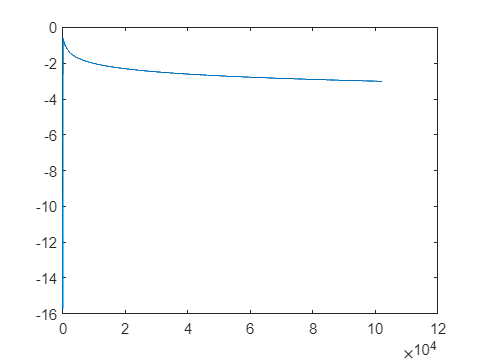

Ad = At(1:p, 1:p);
Bd = Bt(1:p);

[V,D,W] = eig(Ad);

s_nr = - diag(D);
s_nr = s_nr.';
B_mr = Bd'*V;

w_nr = B_mr.^2;
w_nr = w_nr.';
w_nr = w_nr.*exp(0.9*s_nr.');
x = 1:0.01:1024;
x = x.';
y1 = exp(-x*s_nr)*w_nr;
merror = abs(y1- 1 ./(x));
plot(log10(merror))